%% MakeDLCTimeTable

% This script takes the results from DLCAppLite and produces a list of DLC events 

clear;
% This is the table updated from DLCAppLite:
OptoDLCTableName            =            dir('OptoDLCVideo_*Updated.csv');
OptoDLCTable                       =            readtable(fullfile(OptoDLCTableName.folder, OptoDLCTableName.name));

% This is the behavior table
% This is the table:
BpodMEDTableName          =             dir('BpodMEDTable_*.csv');
BpodMEDTable                    =              readtable(fullfile(BpodMEDTableName.folder, BpodMEDTableName.name));

TrialNums = [];
StimTypes = []; % 1. Opto Stim. 0. No stim
DLCTime   = []; % time of DLC trigger (in Bpod time) This is our guide to produce videoes

% loop through all the trials
% Find DLC trials that are no-stim

for i =1:length(OptoDLCTable.TrialNums)
       
    if OptoDLCTable.isGood(i)
        itrial_num      =       OptoDLCTable.TrialNums(i);
        TrialNums       =       [TrialNums; itrial_num];
        DLCTime         =       [DLCTime; BpodMEDTable.tDLC(BpodMEDTable.TrialsBpod == itrial_num)];
        StimTypes       =       [StimTypes; strcmp(OptoDLCTable.OptoStimTypes{i}, 'Stim_DLC')];
    end;
end;

DLCTable = table(TrialNums, StimTypes, DLCTime);

writetable(DLCTable, 'DLCTimeTable.csv')

%% Make ApproachTimeTable

% This script takes the results from DLCAppLite and produces a list of DLC events 

clear;
% This is the table updated from DLCAppLite:
OptoApproachTableName            =            dir('OptoApproachVideo_*.csv');
OptoApproachTable                =            readtable(fullfile(OptoApproachTableName.folder, OptoApproachTableName.name));

% This is the behavior table
% This is the table:
BpodMEDTableName                =             dir('BpodMEDTable_*.csv');
BpodMEDTable                    =              readtable(fullfile(BpodMEDTableName.folder, BpodMEDTableName.name));

TrialNums       = [];
StimTypes       = []; % 1. Opto Stim. 0. No stim
ApproachTime    = []; % time of DLC trigger (in Bpod time) This is our guide to produce videoes

% loop through all the trials
% Find DLC trials that are no-stim

for i =1:length(OptoApproachTable.TrialNums)

        itrial_num      =       OptoApproachTable.TrialNums(i);
        TrialNums       =       [TrialNums; itrial_num];
        ApproachTime    =       [ApproachTime; BpodMEDTable.tApproach(BpodMEDTable.TrialsBpod == itrial_num)];
        StimTypes       =       [StimTypes; strcmp(OptoApproachTable.OptoStimTypes{i}, 'Stim_Approach')];
 
end;

ApproachTable = table(TrialNums, StimTypes, ApproachTime);

writetable(ApproachTable, 'ApproachTimeTable.csv')




DLCTable = readtable('DLCTimeTable.csv')

DLCTable = 146×3 table
    TrialNums    StimTypes    DLCTime
    _________    _________    _______

        4            0        66.423 
        6            0        92.439 
        8            0           124 
       10            0        136.36 
       11            1        153.58 
       12            0         167.8 
       14            0        187.88 
       15            0        210.08 
       16            1         222.6 
       17            0        241.42 
       18            0        254.28 
       19            0        266.92 
       20            1        277.92 
       21            0        294.42 
       24            0         319.2 
       25            0        333.16 


ApproachTable = readtable('ApproachTimeTable.csv')

ApproachTable = 149×3 table
    TrialNums    StimTypes    ApproachTime
    _________    _________    ____________

        4            0           66.179   
        6            0           92.135   
        8            0            123.5   
        9            1           129.51   
       10            0           135.98   
       12            0           167.12   
       13            1           180.34   
       14            0           187.45   
       15            0           209.11   
       17            0           241.14   
       18            0           254.19   
       19            0           266.61   
       21            0           293.78   
       24            0           318.47   
       25            0            332.8   
       26            0           346.56   


% DLCTable.TrialNums
% DLCTable.StimTypes
% DLCTable.DLCTime;


- After 'MakeDLCTimeTable.mlx', we are now ready to produce DLC triggered video from seq file. We will produce video clips for all DLC Opto-Stim trials and a subset of no-stim trials (random number, about half of the total number of no stim trials). We will then feed these videos to a DLC model and construct the paw trajectory, etc. 

- Move seq video files to corresponding session folder e.g., Sessions\20220117 

- Move Wave data to corresponding session folder e.g., Sessions\20220117 

## Step 1: Get frame time and ROI amplitude

% Play video to get a sense of the ROI location
% (Comment this out if the LED location is known)
% PlaySeqFile;

% Get frame information and ROI time
t_min           =       10;
t_sec           =       50;
framerate       =       100;

t_check = [0 500]+(t_min*60+t_sec)*100;
tic
GetSeqFrameInfo([], t_check);
load('FrameInfo.mat')
toc
disp(FrameInfo)
% FrameInfo contains LED information. This allows one to synchronize video data,
% Bpod data, and MED data
% If wavesufer file is available and there is no frame loss, one can also get frame time and perform alignment with that data. 


## Step 2: Gather information, map frame time to bpod timeI H

% BpodMEDTable
BpodMEDTable = readtable(dir('BpodMEDTable*.csv').name);

% Map frame time to Bpod time using cross correlation
tLEDon          =       FindLEDon(FrameInfo.tframe, FrameInfo.ROI); % in ms

ha1 =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.5838 0.3347 0.3412]
            Units: 'normalized'

  Show all properties


ha2 =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.3347 0.3412]
            Units: 'normalized'

  Show all properties


Select threshold, end selection by right click


ha3 =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.5703 0.5838 0.3347 0.3412]
            Units: 'normalized'

  Show all properties


Select mulitple points to define a decision boundary, end selection by right click


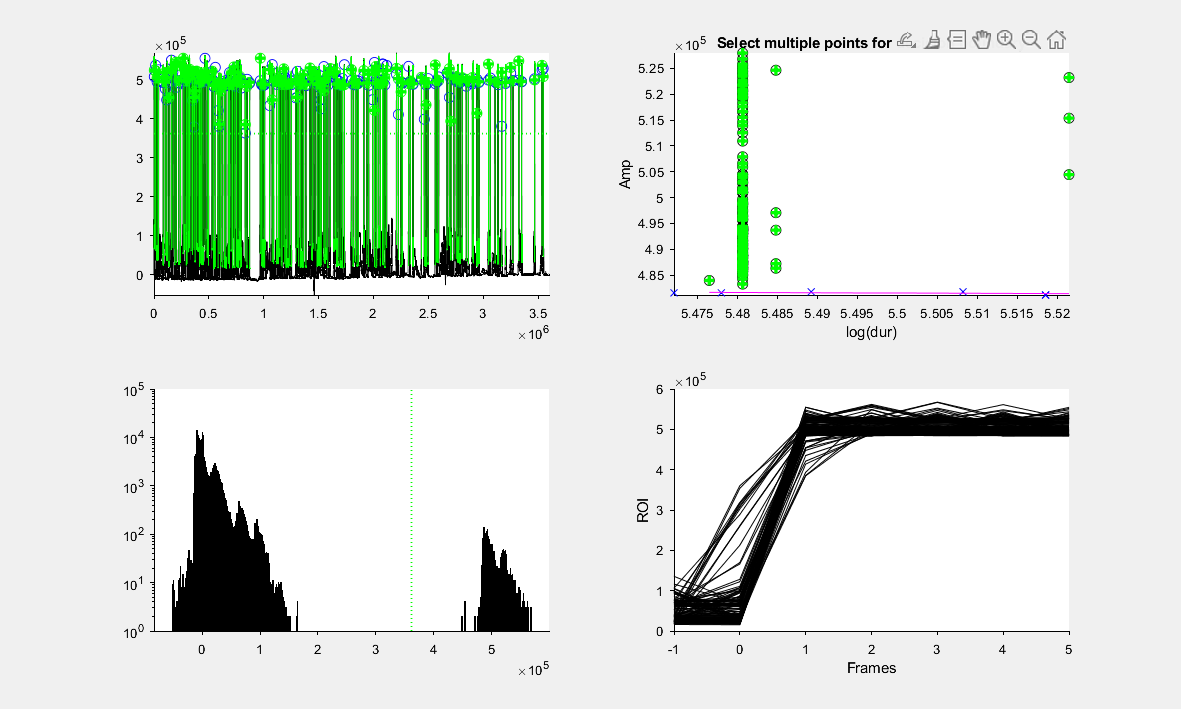

#############################
########## Please wait #########
#############################


ans = 'check seqson 100 of 161'

Elapsed time is 1.682583 seconds.


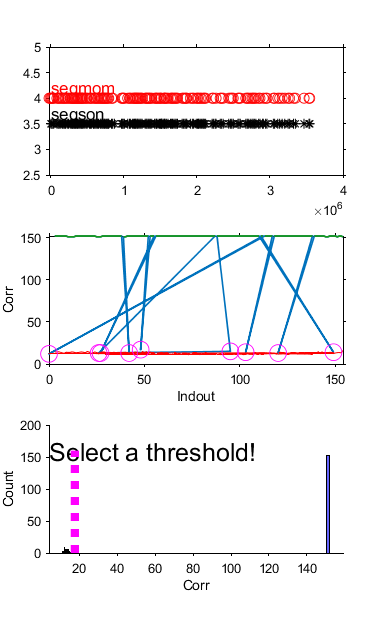

Indout          =       findseqmatchrev(BpodMEDTable.tTrigger(BpodMEDTable.tTrigger>0)*1000, tLEDon, 0, 1);

Define the threshold
Threshold defined
Define the threshold
Threshold defined
#############################
######### Done correcting #######
#############################


#############################
########## Please wait #########
#############################


ans = 'check seqson 100 of 146'

Elapsed time is 2.760517 seconds.


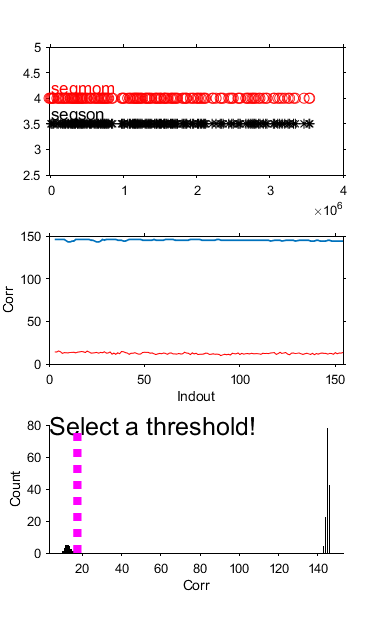

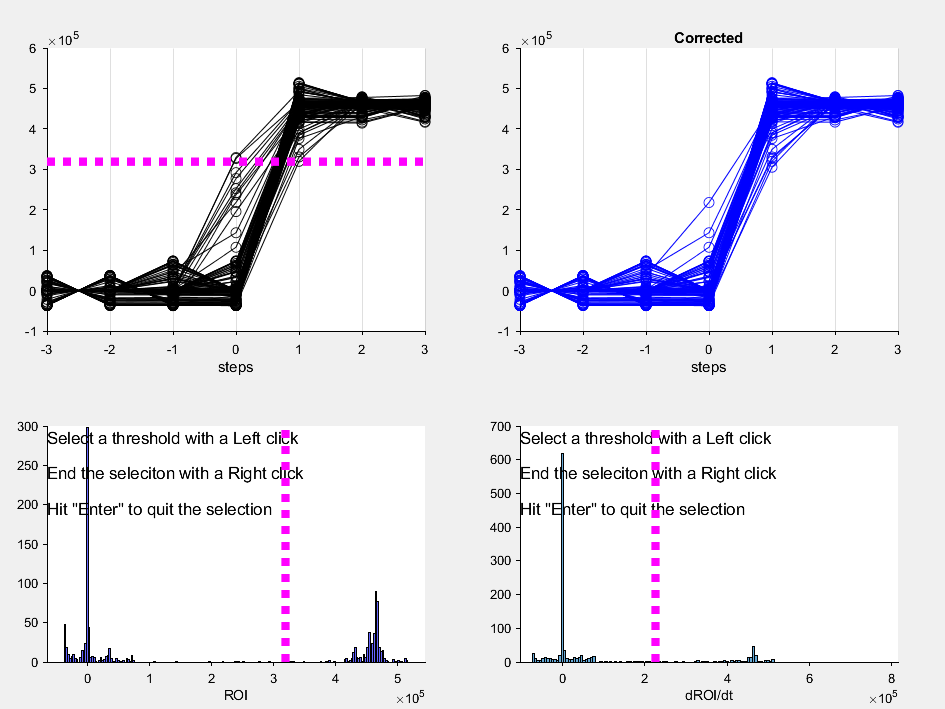


% these LEDon times are the ones that cannot be matched to trigger. It must be a false positive signal that was picked up by mistake in "tLEDon = FindLEDon(tsROI, SummedROI);"
ind_badROI = find(isnan(Indout));
tLEDon(ind_badROI) = []; % remove them
Indout(ind_badROI) = []; % at this point, each LEDon time can be mapped to a trigger time in b (Indout)

FrameInfo.tLEDon = tLEDon;
FrameInfo.Indout = Indout;
%% Now, let's redefine the frame time. Each frame time should be re-mapped to the timespace in b.
% all frame times are here: FrameInfo.tframe
tframes_in_bpod = MapVidFrameTime2B(FrameInfo.tLEDon,  1000*BpodMEDTable.tTrigger(BpodMEDTable.tTrigger>0), Indout, FrameInfo.tframe);
FrameInfo.tFramesInBpod = tframes_in_bpod; % tFramesInBpod is ms

%% Empirically, some events are still not well aligned. In particually, in a small subset of trials, LED starts to light up at trigger time we need to revise these trials.
% some tLEDon need to be revised.
imhappy = 0;
while ~imhappy

    tLEDon = CorrectLEDtimeBpod(BpodMEDTable, FrameInfo); % update tLEDon
    Indout          =       findseqmatchrev(BpodMEDTable.tTrigger(BpodMEDTable.tTrigger>0)*1000, tLEDon, 0, 1);

    % these LEDon times are the ones that cannot be matched to trigger. It must be a false positive signal that was picked up by mistake in "tLEDon = FindLEDon(tsROI, SummedROI);"
    ind_badROI = find(isnan(Indout));
    tLEDon(ind_badROI) = []; % remove them
    Indout(ind_badROI) = []; % at this point, each LEDon time can be mapped to a trigger time in b (Indout)

    FrameInfo.tLEDon = tLEDon;
    FrameInfo.Indout = Indout;
    %% Now, let's redefine the frame time. Each frame time should be re-mapped to the timespace in b.
    % all frame times are here: FrameInfo.tframe
    tframes_in_bpod = MapVidFrameTime2B(FrameInfo.tLEDon,  1000*BpodMEDTable.tTrigger(BpodMEDTable.tTrigger>0), Indout, FrameInfo.tframe);
    FrameInfo.tFramesInBpod = tframes_in_bpod; % tFramesInBpod is ms

    clc
    reply = input('Are you happy? Y/N [Y]', 's');
    if isempty(reply)
        reply = 'Y';
    end;
    if strcmp(reply, 'Y')  ||  strcmp(reply, 'y')
        imhappy = 1;
    else
        imhappy =0;
    end
end;


save FrameInfo FrameInfo

% % Make a table
% 
% tFrames             =       FrameInfo.tframe';
% tFrams2Bpodms       =       tframes_in_bpod';   % corresponding time in bpod   
% SeqFileIdx          =       FrameInfo.SeqFileIndx';
% SeqFrameIndx        =       FrameInfo.SeqFrameIndx';
% SeqVidFiles         =       cell(length(tFrames), 1);
% 
% for i = 1:length(tFrames)
%     SeqVidFiles{i} = FrameInfo.SeqVidFile{FrameInfo.SeqFileIndx};
% end;
% 
% FrameTable = table(tFrames, tFrams2Bpodms, SeqVidFiles, SeqFileIdx, SeqFrameIndx);
% FrameTableName =  ['FrameInfo' '.csv'];
% writetable(FrameTable, FrameTableName);


## Step 3: Make video clips from these two types of events: DLC or approach

   Load a bunch of data

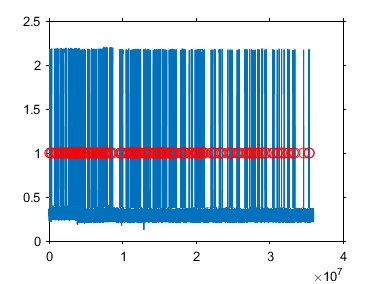

#############################
########## Please wait #########
#############################


ans = 'check seqson 100 of 160'

Elapsed time is 1.485884 seconds.


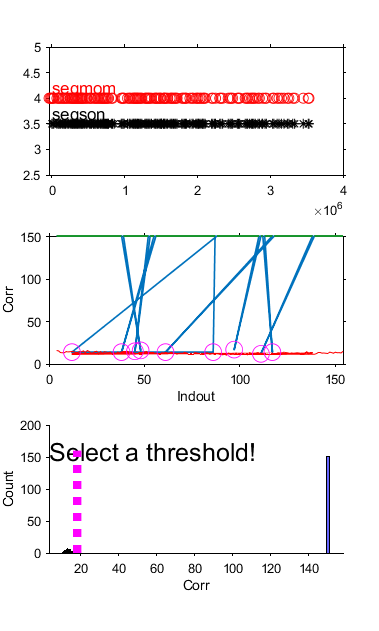

% 
% BpodMEDTable
BpodMEDTable = readtable(dir('BpodMEDTable*.csv').name);

h5file = dir('*.h5');
WSOut = ReadH5Opto(h5file.name);  % this gives data from wave surfer
% Use Trigger information to map time in WSOut to Bpod
WSOut = MapWave2Bpod(WSOut, BpodMEDTable.tTrigger(BpodMEDTable.tTrigger>0));


load('WSOut.mat')
load('FrameInfo.mat')
disp(FrameInfo)

           tframe: [0 20 30 40 50 60 70 80 90 100 110 120 130 … ]
             mask: [800×904 logical]
              ROI: [741986 744231 743265 743158 742657 743470 … ]
       SeqVidFile: {'20220121-12-47-15.000.seq'}
      SeqFileIndx: [1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 … ]
     SeqFrameIndx: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 … ]
          MEDfile: '2022-01-21_12h41m_Subject Claire.txt'
           tLEDon: [2390 14600 28220 41550 84710 102740 136241 … ]
           Indout: [3 4 5 6 7 8 10 11 12 13 14 15 16 17 18 19 … ]
    tFramesInBpod: [5.3442e+04 5.3462e+04 5.3472e+04 5.3482e+04 … ]



## Step 4: Run these codes in command window. 

3 files need to be loaded to the workspace

1. BpoMEDTable

2. FrameInfo

3. WSOut




% Make DLC stim videos
DLCTable                =           readtable('DLCTimeTable.csv')
DLCStimTime             =           DLCTable.DLCTime(DLCTable.StimTypes==1); %in ms
DLCNoStimTime           =           DLCTable.DLCTime(DLCTable.StimTypes==0); %in ms
rng(10);
DLCNoStimTime           =           DLCNoStimTime(randperm(length(DLCNoStimTime), round(0.5*length(DLCNoStimTime))));


Extrct  =  "MakeSeqClips(BpodMEDTable, FrameInfo, WSOut, DLCStimTime, 'Event', 'DLC_Stim'," + ...
    "'Pre', 500, 'Post', 2500, 'ANM', cell2mat(extractBetween(FrameInfo.MEDfile, 'Subject ', '.txt'))," + ...
    " 'BehaviorType','ApproachDLCMixOptoStim, DLS', 'Session', extractBefore(FrameInfo.MEDfile, '_')," + ...
    " 'Remake', 1);";
eval(Extrct)

Extrct  =  "MakeSeqClips(BpodMEDTable, FrameInfo, WSOut, DLCNoStimTime, 'Event', 'DLC_NoStim'," + ...
    "'Pre', 500, 'Post', 2500, 'ANM', cell2mat(extractBetween(FrameInfo.MEDfile, 'Subject ', '.txt'))," + ...
    " 'BehaviorType','ApproachDLCMixOptoStim, DLS', 'Session', extractBefore(FrameInfo.MEDfile, '_')," + ...
    " 'Remake', 1);";
eval(Extrct)


% Make Approach stim videos
ApproachTable                =           readtable('ApproachTimeTable.csv')
ApproachStimTime             =           ApproachTable.ApproachTime(ApproachTable.StimTypes==1); %in ms
ApproachNoStimTime           =           ApproachTable.ApproachTime(ApproachTable.StimTypes==0); %in ms
rng(10);
ApproachNoStimTime           =           ApproachNoStimTime(randperm(length(ApproachNoStimTime), round(0.5*length(ApproachNoStimTime))));


Extrct  =  "MakeSeqClips(BpodMEDTable, FrameInfo, WSOut, ApproachStimTime, 'Event', 'Approach_Stim'," + ...
    "'Pre', 500, 'Post', 2500, 'ANM', cell2mat(extractBetween(FrameInfo.MEDfile, 'Subject ', '.txt'))," + ...
    " 'BehaviorType','ApproachDLCMixOptoStim, DLS', 'Session', extractBefore(FrameInfo.MEDfile, '_')," + ...
    " 'Remake', 0);";
eval(Extrct)

Extrct  =  "MakeSeqClips(BpodMEDTable, FrameInfo, WSOut, ApproachNoStimTime, 'Event', 'Approach_NoStim'," + ...
    "'Pre', 500, 'Post', 2500, 'ANM', cell2mat(extractBetween(FrameInfo.MEDfile, 'Subject ', '.txt'))," + ...
    " 'BehaviorType','ApproachDLCMixOptoStim, DLS', 'Session', extractBefore(FrameInfo.MEDfile, '_')," + ...
    " 'Remake', 0);";
eval(Extrct)